# Réseaux de neurones

Les valeurs dans le rapport ont été faites par rapport aux données faites avant réentrainement de vérification avant le rendu donc il est possible que les valeurs aient changé mais les observations et conclusions restent inchangées.

## Introduction

A travers cet exercice, nous allons comprendre comment fonctionne un réseau de neurone et étudier l'influence que peut avoir certains paramètres du réseau sur la qualité du réseau.

Un réseau de neurones est une structure informatique conçue pour simuler le fonctionnement des neurones biologiques. Il se compose de nœuds interconnectés (neurones artificiels) qui traitent les données en appliquant des fonctions mathématiques. Ces réseaux apprennent à effectuer des tâches en ajustant les poids des connexions en fonction des données d'entrée, ce qui permet de modéliser des relations complexes et non linéaires dans les données. 

Les réseaux de neurones sont très largement utilisés car ils ont l'atout de pouvoir modéliser n'importe quelle fonction. De plus, ils sont facilement compréhensibles et lisibles. Ainsi, la plupart des application du Deep Learning se font avec des réseaux de neurones.

### Chargement du dataset

Nous travaillerons avec le jeu de données MNIST  qui est un ensemble standard dans le domaine de l'apprentissage automatique, utilisé pour la classification et la reconnaissance d'images. Il comprend 70 000 images en niveaux de gris de chiffres écrits manuellement, chacune de taille 28x28 pixels. Ces images représentent des chiffres allant de 0 à 9. L'objectif est de développer des modèles capables de reconnaître et de classifier ces chiffres avec précision. MNIST est largement utilisé pour tester et valider les algorithmes de reconnaissance d'images, en particulier ceux basés sur des réseaux de neurones.


imdsTrain = imageDatastore("DatasetMNIST/MNIST Dataset JPG format/MNIST - JPG - training","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation ,imdsPrediction] = splitEachLabel(imdsTrain,0.7,0.2,0.1,'randomized');
% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([28 28 1],imdsTrain);
augimdsValidation = augmentedImageDatastore([28 28 1],imdsValidation);
augimdsPrediction = augmentedImageDatastore([28 28 1],imdsPrediction);

### Paramètres 

Il y a différents paramètres à prendre en compte dans la construction d'un réseau et de l'étude de son influence:

- Nombre de couche

- Activateurs (reluLayer, leakyReluLayer, clippedReluLayer, tanhLayer, eluLayer, geluLayer, swishLayer, functionLayer)

- Solveurs (sgdm, adam, rmsprop)

- Hyperparamètres (InitialRate, MaxEpochs, MiniBatchsize, etc...)  

### Explication du réseau 

Nous allons chosir une réseau de neurone basique et simple que l'on va essayer de comprendre:

`layers0= [imageInputLayer(inputSize,options)`

    `fullyConnectedLayer(outputSize,options)`

    `reluLayer`

    `fullyConnectedLayer(outputSize,options)`

    `softmaxLayer`

    `classificationLayer];`

`deepNetworkDesigner(layers0)`

`options0 = trainingOptions(solverName,InitialLearnRate=,MaxEpochs=,`

    `MiniBatchsize=, ValidationFrequency=, Plots=,ValidationData=,options)`

`[net0, traininfo0] = trainNetwork(imdsTrain,layers0,options0);`

`deepNetworkDesigner(layers0);`

`analyzeNetwork(layers0);`

`[label0, score0] = classify(net0,imdsPrediction)`

- `layers0` : Cette variable définit l'architecture du réseau de neurones. Elle comprend une couche d'entrée d'image, des couches entièrement connectées, une fonction d'activation ReLU (rectified linear unit), une couche de softmax et une couche de classification. Chaque ligne dans le code représente une couche différente dans le réseau.

- `deepNetworkDesigner(layers0)` : Cette fonction ouvre l'application Deep Network Designer avec les couches spécifiées, permettant une inspection visuelle et une modification de l'architecture du réseau

- `options0 = trainingOptions()` : Cette ligne est utilisée pour définir les options d'entraînement pour le réseau de neurones. Elle définit divers paramètres tels que le solveur, le taux d'apprentissage initial, le nombre maximal d'époques, la taille des mini-lots, la fréquence de validation, les graphiques et les données de validation.

- `[net0, traininfo0] = trainNetwork(imdsTrain,layers0,options0)` : Cette ligne entraîne le réseau de neurones en utilisant les données d'entraînement, les couches et les options d'entraînement spécifiées. Elle renvoie le réseau entraîné (`net0`) et les informations d'entraînement (`traininfo0`).

- `analyzeNetwork(layers0)` : Cette fonction est utilisée pour analyser l'architecture du réseau de neurones définie par `layers0`.

- `[label0, score0] = classify(net0,imdsPrediction)` : Après l'entraînement, cette ligne utilise le réseau entraîné `net0` pour classer les images dans l'ensemble de données `imdsPrediction` et renvoie les étiquettes et les scores des prédictions.

## Etude de l'influence des hyperparamètres et paramètres de couche

### Influence du nombre de neurones de la première couche

Nous avons choisi des nombres arbitraires de couche de neurones croissantes (128,400,1000) avec des écarts signficativement grands afin de pouvoir observer une différence et en tirer des conclusions.

layersN1 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

layersN2 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(400)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

layersN3 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1000)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

optionsNA = trainingOptions("sgdm", ...
    InitialLearnRate=0.001,...   
    MaxEpochs=5, ...
    MiniBatchSize=64, ...
    ValidationFrequency=30, ...
    ValidationData=imdsValidation)

optionsNA =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 5
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 64
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 30
              ValidationPatience: Inf



[netN1, traininfoN1] = trainNetwork(imdsTrain,layersN1,optionsNA)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |        9.38% |       22.08% |     148.5869 |      85.5231 |          0.0010 |
|       1 |          30 |       00:00:02 |       65.62% |       65.38% |       5.7215 |       6.7186 |          0.0010 |
|       1 |          50 |       00:00:02 |       45.31% |              |       2.3779 |              |          0.0010 |
|       1 |          60 |       00:00:03 |       43.75% |       51.12% |       1.4969 |   

netN1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoN1 = struct with fields:
               TrainingLoss: [148.5869 84.9977 90.1524 87.6250 60.8064 78.9422 40.7701 40.7367 20.7318 10.9475 10.1749 15.1154 16.3104 16.9695 13.8405 11.2079 12.2858 8.0468 5.0525 6.6501 6.1142 9.5682 3.5320 10.5072 9.0750 7.8119 … ] (1×3280 double)
           TrainingAccuracy: [9.3750 25 37.5000 34.3750 59.3750 50 57.8125 48.4375 62.5000 65.6250 70.3125 73.4375 67.1875 65.6250 60.9375 73.4375 64.0625 71.8750 73.4375 73.4375 70.3125 67.1875 82.8125 59.3750 68.7500 71.8750 75 … ] (1×3280 double)
             ValidationLoss: [85.5231 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 6.7186 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [22.0833 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 65.3750 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN Na

[netN2, traininfoN2] = trainNetwork(imdsTrain,layersN2,optionsNA)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       14.06% |       15.57% |     160.0711 |     257.5634 |          0.0010 |
|       1 |          30 |       00:00:02 |       68.75% |       75.33% |       6.4149 |       4.4995 |          0.0010 |
|       1 |          50 |       00:00:02 |       67.19% |              |       6.1383 |              |          0.0010 |
|       1 |          60 |       00:00:03 |       81.25% |       73.07% |       1.3086 |   

netN2 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoN2 = struct with fields:
               TrainingLoss: [160.0711 272.7632 303.4088 368.1252 141.5774 70.4835 39.7488 24.5743 39.7665 32.8624 9.2498 13.5224 14.4127 15.0761 16.6532 8.6794 8.1240 8.6129 10.4622 5.7465 7.0525 9.0729 5.2922 8.0685 5.8116 3.5883 … ] (1×3280 double)
           TrainingAccuracy: [14.0625 7.8125 20.3125 34.3750 45.3125 56.2500 56.2500 68.7500 56.2500 50 75 64.0625 75 68.7500 68.7500 79.6875 76.5625 78.1250 76.5625 81.2500 67.1875 75 71.8750 67.1875 68.7500 71.8750 78.1250 70.3125 … ] (1×3280 double)
             ValidationLoss: [257.5634 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 4.4995 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [15.5750 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 75.3250 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN N

[netN3, traininfoN3] = trainNetwork(imdsTrain,layersN3,optionsNA)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        4.69% |       24.39% |     132.1279 |     204.8111 |          0.0010 |
|       1 |          30 |       00:00:03 |       71.88% |       80.16% |       8.7828 |       4.6718 |          0.0010 |
|       1 |          50 |       00:00:03 |       76.56% |              |       6.5695 |              |          0.0010 |
|       1 |          60 |       00:00:04 |       85.94% |       80.56% |       0.8611 |   

netN3 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoN3 = struct with fields:
               TrainingLoss: [132.1279 232.7707 335.1949 281.8710 151.1568 170.7894 101.0013 65.1525 49.6389 38.4877 12.8704 5.9441 17.5764 14.7269 5.0281 8.4080 6.1935 5.6571 6.0383 11.0525 7.1433 3.2703 4.1266 10.6746 15.0812 3.4962 … ] (1×3280 double)
           TrainingAccuracy: [4.6875 20.3125 17.1875 43.7500 64.0625 50 68.7500 68.7500 65.6250 64.0625 71.8750 79.6875 67.1875 73.4375 82.8125 75 79.6875 81.2500 81.2500 70.3125 75 87.5000 81.2500 73.4375 76.5625 85.9375 89.0625 … ] (1×3280 double)
             ValidationLoss: [204.8111 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 4.6718 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [24.3917 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 80.1583 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN N


deepNetworkDesigner(layersN1)
deepNetworkDesigner(layersN2)
deepNetworkDesigner(layersN3)

analyzeNetwork(layersN1)
analyzeNetwork(layersN2)
analyzeNetwork(layersN3)

[labelN1, scoreN1] = classify(netN1,imdsPrediction);
[labelN2, scoreN2] = classify(netN2,imdsPrediction);
[labelN3, scoreN3] = classify(netN3,imdsPrediction);


L'influence du nombre de neurones dans les couches de réseaux de neurones est illustrée par les résultats de trois modèles avec des nombres croissants de neurones : 128, 400 et 1000. Le premier modèle avec 128 neurones atteint une précision de 91,42% et une perte de 0,4378. En augmentant à 400 neurones, la précision s'améliore à 92,15%, et la perte diminue à 0,4259. Le troisième modèle, avec 1000 neurones, montre une amélioration supplémentaire, avec une précision de 94,96% et une perte réduite à 0,3163. Ces résultats indiquent que l'augmentation du nombre de neurones peut améliorer la performance du modèle, probablement en permettant une meilleure capture des caractéristiques et des complexités des données.

#### Vérification par des métriques

#### Matrice de confusion

Nous évaluerons comme métrique une matrice de confusion, l'accuracy et la loss:

L'accuracy (précision) et la loss (perte) sont des mesures clés pour évaluer les performances d'un réseau de neurones. L'accuracy mesure le pourcentage de prédictions correctes parmi l'ensemble total des prédictions. Une accuracy plus élevée indique une meilleure performance du modèle. La loss, quant à elle, est un indicateur de l'erreur entre les prédictions du modèle et les valeurs réelles. Une loss faible signifie que le modèle est précis dans ses prédictions.

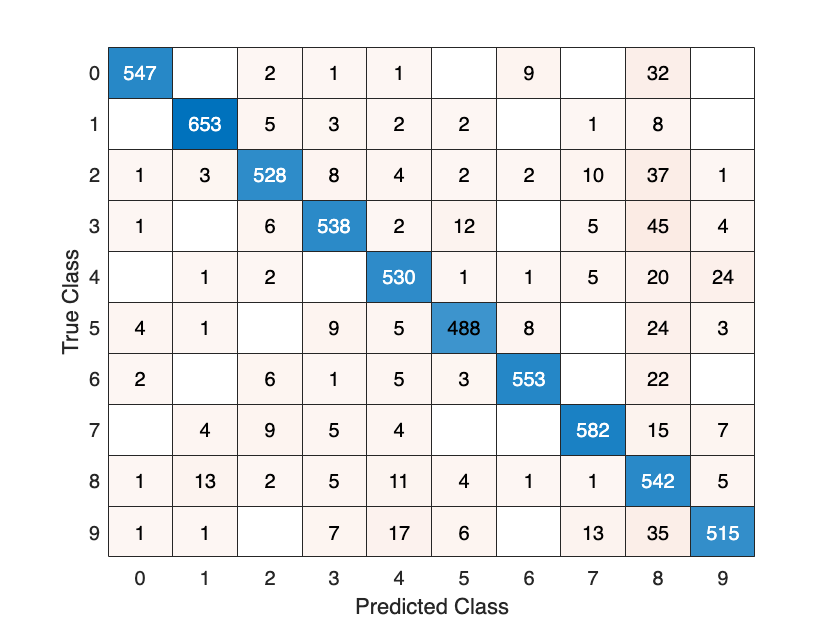

confusionchart(imdsPrediction.Labels, categorical(labelN1));

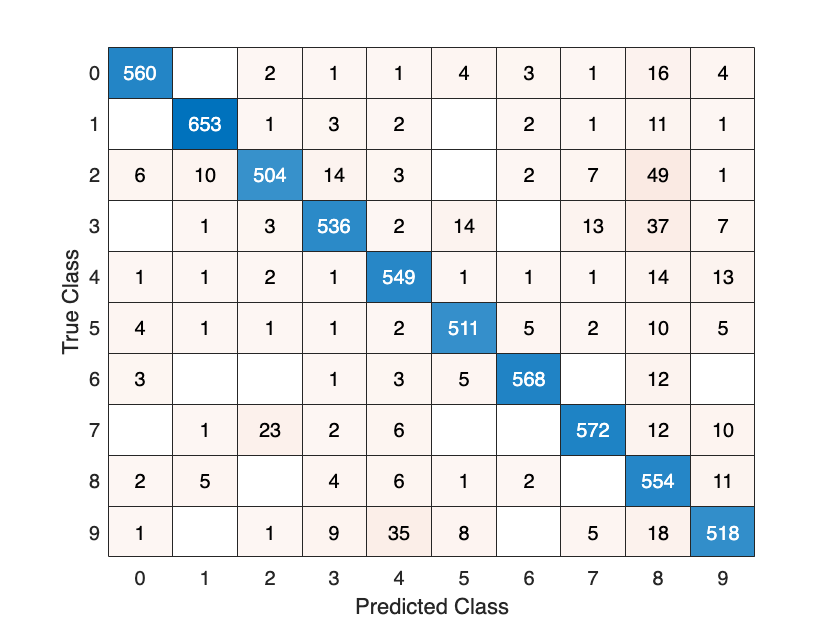


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelN1));

confusionchart(imdsPrediction.Labels, categorical(labelN2));

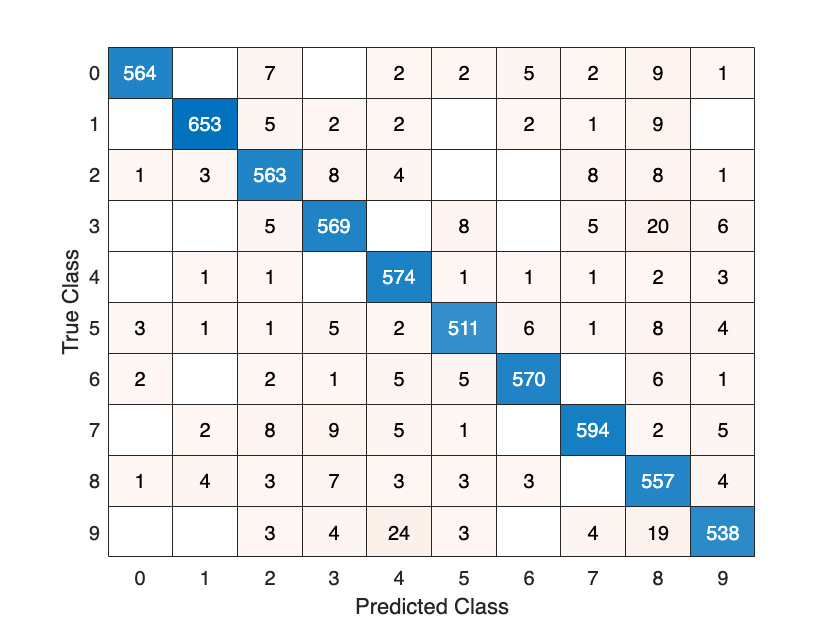


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelN2));

confusionchart(imdsPrediction.Labels, categorical(labelN3));


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelN3));


Dans l'ensemble, les valeurs prédites sont justes, c'est ce que l'on appelle les "True Positive" mis à part la valeur 8 qui a du mal à prédire avec excatitudes et qui présente les plus grandes valeurs de faux positifs. De plus, la valeur 1 est la plus prédite car surement présentant moins d'ambiguité avec un seul trait. La moins bien prédite est la 5

### Influence des activateurs

Nous avons choisi 4 activateurs (reluLayer,swishLayer,eluLayer,tanhLayer) avec des écarts signficativement grands afin de pouvoir observer une différence et en tirer des conclusions.

layersA1 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

layersA2 = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(128)
    swishLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

layersA3= [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(128)
    eluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

layersA4 = [imageInputLayer([28 28 1])
    fullyConnectedLayer(128)
    tanhLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

[netA1, traininfoA1] = trainNetwork(imdsTrain,layersA1,optionsNA)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        7.81% |       29.60% |     144.0432 |      97.1532 |          0.0010 |
|       1 |          30 |       00:00:02 |       60.94% |       58.88% |       7.7338 |       7.4257 |          0.0010 |
|       1 |          50 |       00:00:02 |       54.69% |              |       2.3987 |              |          0.0010 |
|       1 |          60 |       00:00:03 |       62.50% |       59.06% |       1.8598 |   

netA1 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoA1 = struct with fields:
               TrainingLoss: [144.0432 99.1088 115.4242 41.1062 59.6638 47.6867 63.2127 26.8026 25.5756 47.4625 37.0496 31.0411 20.1008 15.6239 15.8096 15.1045 17.8966 11.0958 20.1128 8.2223 15.5036 8.8245 20.9692 9.2228 12.5648 4.8836 … ] (1×3280 double)
           TrainingAccuracy: [7.8125 39.0625 23.4375 57.8125 57.8125 56.2500 57.8125 76.5625 67.1875 59.3750 59.3750 62.5000 65.6250 70.3125 78.1250 60.9375 68.7500 68.7500 68.7500 82.8125 68.7500 78.1250 60.9375 78.1250 68.7500 … ] (1×3280 double)
             ValidationLoss: [97.1532 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 7.4257 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [29.6000 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 58.8833 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN Na

[netA2, traininfoA2] = trainNetwork(imdsTrain,layersA2,optionsNA)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       12.50% |       18.67% |     146.7837 |      89.4822 |          0.0010 |
|       1 |          30 |       00:00:02 |       57.81% |       64.27% |       5.4407 |       3.8171 |          0.0010 |
|       1 |          50 |       00:00:02 |       57.81% |              |       1.4997 |              |          0.0010 |
|       1 |          60 |       00:00:03 |       59.38% |       57.61% |       1.7032 |   

netA2 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoA2 = struct with fields:
               TrainingLoss: [146.7837 75.2992 106.5457 126.5602 83.5850 121.4540 160.9401 147.2703 65.8176 42.0328 25.1885 21.8427 11.5156 9.6463 8.9263 5.6020 13.1882 6.9799 7.5626 11.5960 5.0815 10.7010 7.5853 4.2937 3.2415 3.1072 … ] (1×3280 double)
           TrainingAccuracy: [12.5000 18.7500 25 50 60.9375 39.0625 39.0625 42.1875 48.4375 60.9375 64.0625 62.5000 70.3125 62.5000 71.8750 71.8750 67.1875 71.8750 73.4375 64.0625 75 62.5000 68.7500 62.5000 76.5625 68.7500 75 60.9375 … ] (1×3280 double)
             ValidationLoss: [89.4822 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 3.8171 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [18.6667 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 64.2667 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN

[netA3, traininfoA3] = trainNetwork(imdsTrain,layersA3,optionsNA)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:01 |        7.81% |       28.60% |     123.1347 |     101.4495 |          0.0010 |
|       1 |          30 |       00:00:02 |       50.00% |       65.92% |       7.2535 |       5.2266 |          0.0010 |
|       1 |          50 |       00:00:02 |       75.00% |              |       3.7610 |              |          0.0010 |
|       1 |          60 |       00:00:03 |       57.81% |       65.70% |       2.5583 |   

netA3 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoA3 = struct with fields:
               TrainingLoss: [123.1347 114.3093 95.9691 153.1334 122.7225 61.7823 91.0529 54.0919 59.1797 28.7656 18.1433 18.3491 31.6712 19.0536 14.0203 15.3727 6.3761 5.8761 12.9398 8.8072 21.7132 5.5565 6.0608 6.7243 5.5682 3.5656 … ] (1×3280 double)
           TrainingAccuracy: [7.8125 23.4375 34.3750 32.8125 54.6875 67.1875 56.2500 60.9375 50 64.0625 70.3125 71.8750 59.3750 65.6250 62.5000 71.8750 70.3125 79.6875 64.0625 67.1875 57.8125 68.7500 62.5000 70.3125 60.9375 70.3125 … ] (1×3280 double)
             ValidationLoss: [101.4495 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 5.2266 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [28.6000 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 65.9167 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 

[netA4, traininfoA4] = trainNetwork(imdsTrain,layersA4,optionsNA)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       10.94% |        8.36% |       2.9119 |       3.0322 |          0.0010 |
|       1 |          30 |       00:00:02 |       53.12% |       48.78% |       1.5681 |       1.5031 |          0.0010 |
|       1 |          50 |       00:00:02 |       56.25% |              |       1.2553 |              |          0.0010 |
|       1 |          60 |       00:00:03 |       76.56% |       65.92% |       0.9179 |   

netA4 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoA4 = struct with fields:
               TrainingLoss: [2.9119 3.0872 2.9798 3.0674 2.8013 3.0388 2.6304 2.7261 2.4864 2.6002 2.4657 2.5453 2.3845 2.7041 2.1231 2.2573 1.8702 1.9598 2.0105 2.0328 2.0410 1.9563 1.9389 2.0166 1.7595 1.4481 1.6696 1.5791 1.6181 … ] (1×3280 double)
           TrainingAccuracy: [10.9375 6.2500 4.6875 6.2500 9.3750 3.1250 14.0625 14.0625 15.6250 18.7500 14.0625 15.6250 17.1875 7.8125 28.1250 28.1250 37.5000 31.2500 23.4375 29.6875 31.2500 39.0625 26.5625 34.3750 40.6250 51.5625 … ] (1×3280 double)
             ValidationLoss: [3.0322 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 1.5031 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [8.3583 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 48.7833 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 


deepNetworkDesigner(layersA1)
deepNetworkDesigner(layersA2)
deepNetworkDesigner(layersA3)
deepNetworkDesigner(layersA4)


analyzeNetwork(layersA1)
analyzeNetwork(layersA2)
analyzeNetwork(layersA3)
analyzeNetwork(layersA4)

[labelA1, scoreA1] = classify(netA1,imdsPrediction);
[labelA2, scoreA2] = classify(netA2,imdsPrediction);
[labelA3, scoreA3] = classify(netA3,imdsPrediction);
[labelA4, scoreA4] = classify(netA4,imdsPrediction);

L'influence des différentes fonctions d'activation sur les performances d'un réseau de neurones est démontrée par quatre modèles utilisant reluLayer, swishLayer, eluLayer et tanhLayer. Avec reluLayer, le modèle atteint une précision de 90,625% et une perte de 0,4886. En utilisant swishLayer, la précision augmente légèrement à 91,3583% et la perte diminue à 0,4417. Avec eluLayer, on observe une précision de 92,2333% et une perte de 0,3976, indiquant une amélioration supplémentaire. Enfin, tanhLayer produit une précision de 91,5583% mais avec une perte significativement réduite à 0,2912, suggérant une meilleure gestion des erreurs malgré une précision légèrement inférieure.

En classant les performances des modèles de réseaux de neurones selon leurs fonctions d'activation du moins bon au meilleur, on observe la séquence suivante : reluLayer est le moins performant, suivi de swishLayer . TanhLayer  se positionne au milieu. Le meilleur résultat est obtenu avec eluLayer alliant précision et perte minimale.

#### Vérification par des métriques

#### Matrice de confusion

Nous évaluerons comme métrique une matrice de confusion, l'accuracy et la loss:

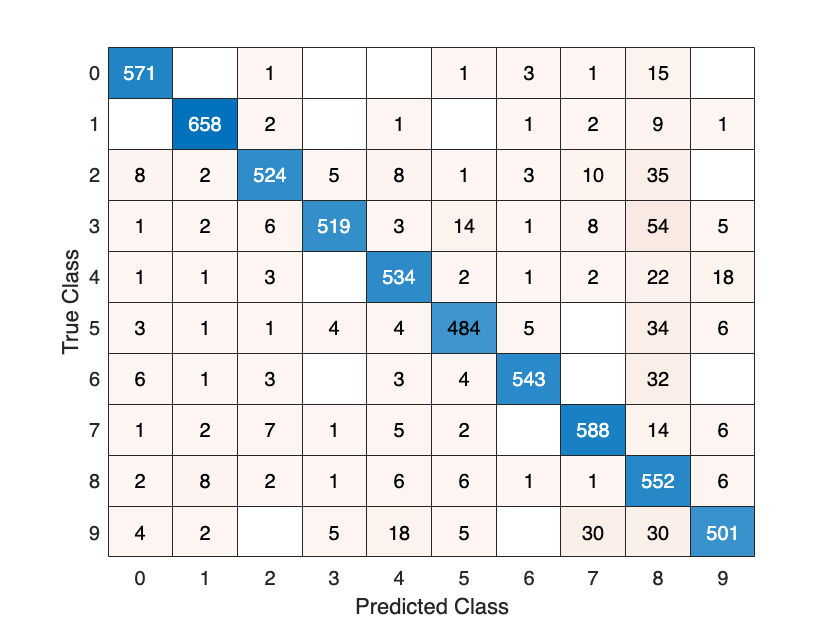

confusionchart(imdsPrediction.Labels, categorical(labelA1));

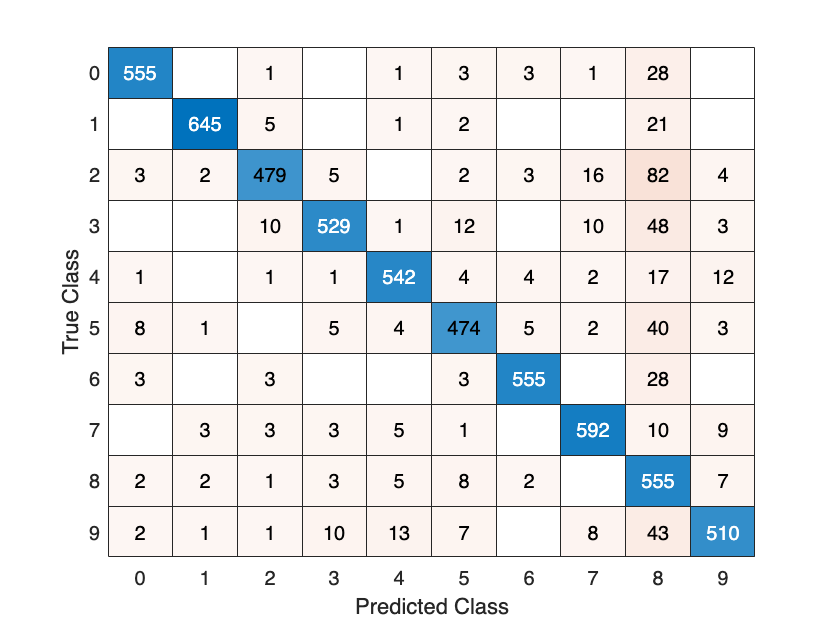


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelA1));

confusionchart(imdsPrediction.Labels, categorical(labelA2));

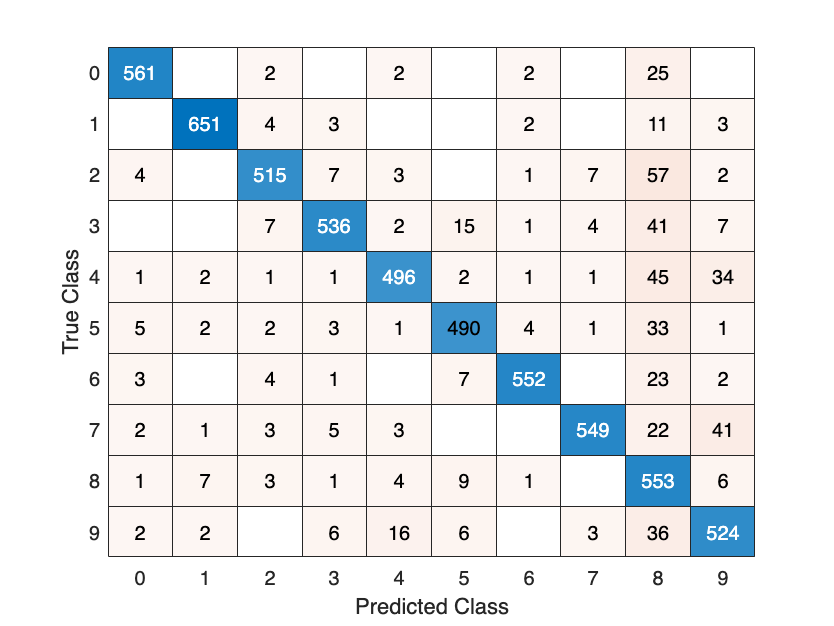


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelA2));

confusionchart(imdsPrediction.Labels, categorical(labelA3));

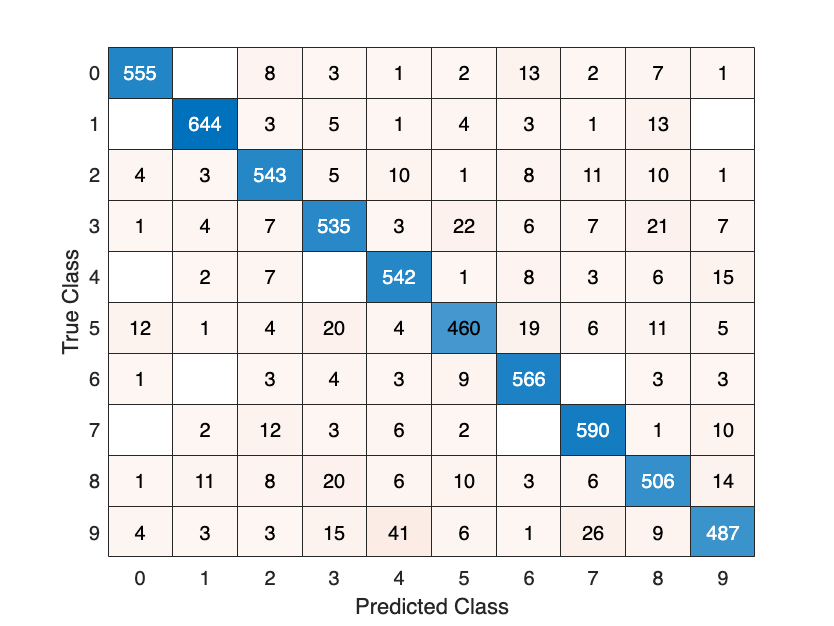


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelA3));

confusionchart(imdsPrediction.Labels, categorical(labelA4));


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelA4));

confusionchart(imdsPrediction.Labels, categorical(labelA4));

Ici de même et c'est une conclusion que l'on va pouvoir appliquer à chaque étude d'influences, le 5 et le 8 sont les valeurs les moins bien prédites car présentant le plus d'ambiguité contrairement au 1.

### Influence des solveurs

Nous avons choisi 3 solveurs (adam, sgdm,rmsprop) avec des écarts signficativement grands afin de pouvoir observer une différence et en tirer des conclusions.

layersS = [imageInputLayer([28 28 1])
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

optionsS1 = trainingOptions("adam", ...
    InitialLearnRate=0.001,...   
    MaxEpochs=5, ...
    MiniBatchSize=64, ...
    ValidationFrequency=30, ...
    ValidationData=imdsValidation)

optionsS1 =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 5
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 64
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Image



optionsS2 = trainingOptions("sgdm", ...
    InitialLearnRate=0.001,...   
    MaxEpochs=5, ...
    MiniBatchSize=64, ...
    ValidationFrequency=30, ...
    ValidationData=imdsValidation)

optionsS2 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 5
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 64
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 30
              ValidationPatience: Inf



optionsS3 = trainingOptions("rmsprop", ...
    InitialLearnRate=0.001,...   
    MaxEpochs=5, ...
    MiniBatchSize=64, ...
    ValidationFrequency=30, ...
    ValidationData=imdsValidation)

optionsS3 =   TrainingOptionsRMSProp with properties:

      SquaredGradientDecayFactor: 0.9000
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-03
                       MaxEpochs: 5
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 64
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationF


[netSa, traininfoSa] = trainNetwork(imdsTrain,layersS,optionsS1)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       15.62% |       18.88% |     121.9662 |      76.9333 |          0.0010 |
|       1 |          30 |       00:00:02 |       78.12% |       77.27% |      14.3777 |      10.3176 |          0.0010 |
|       1 |          50 |       00:00:02 |       89.06% |              |       2.8373 |              |          0.0010 |
|       1 |          60 |       00:00:03 |       81.25% |       81.01% |       4.9543 |   

netSa =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoSa = struct with fields:
               TrainingLoss: [121.9662 81.3394 59.3710 59.0245 50.4208 45.4932 26.2499 25.7132 32.0400 17.6910 12.7707 16.1608 16.5740 29.3933 17.9055 21.1976 20.4102 11.9769 23.1170 17.7259 5.4803 7.3554 12.0559 10.0123 9.0742 12.5742 … ] (1×3280 double)
           TrainingAccuracy: [15.6250 15.6250 26.5625 34.3750 35.9375 40.6250 51.5625 53.1250 43.7500 67.1875 64.0625 68.7500 60.9375 62.5000 71.8750 68.7500 70.3125 71.8750 62.5000 73.4375 82.8125 82.8125 81.2500 78.1250 79.6875 … ] (1×3280 double)
             ValidationLoss: [76.9333 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 10.3176 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [18.8833 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 77.2667 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 

[netSb, traininfoSb] = trainNetwork(imdsTrain,layersS,optionsS2)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |        9.38% |       21.39% |     148.7485 |     147.2439 |          0.0010 |
|       1 |          30 |       00:00:02 |       59.38% |       59.05% |       2.6281 |       2.5498 |          0.0010 |
|       1 |          50 |       00:00:02 |       50.00% |              |       2.2707 |              |          0.0010 |
|       1 |          60 |       00:00:03 |       64.06% |       56.11% |       1.1855 |   

netSb =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoSb = struct with fields:
               TrainingLoss: [148.7485 168.1188 124.4554 165.3383 75.3987 96.4995 55.3149 42.6023 25.2500 8.7925 9.1622 12.5265 7.4236 12.8828 7.2603 6.7167 8.0986 5.9175 5.5449 4.7738 2.9801 2.9072 3.5715 4.4209 3.5703 2.1416 2.2265 … ] (1×3280 double)
           TrainingAccuracy: [9.3750 12.5000 43.7500 26.5625 56.2500 37.5000 50 51.5625 64.0625 65.6250 67.1875 62.5000 67.1875 64.0625 67.1875 62.5000 59.3750 56.2500 57.8125 62.5000 60.9375 59.3750 60.9375 54.6875 53.1250 71.8750 … ] (1×3280 double)
             ValidationLoss: [147.2439 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 2.5498 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [21.3917 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 59.0500 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 

[netSc, traininfoSc] = trainNetwork(imdsTrain,layersS,optionsS3)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |        7.81% |       22.28% |     148.6198 |     153.2073 |          0.0010 |
|       1 |          30 |       00:00:02 |       64.06% |       74.72% |      20.2961 |      11.8334 |          0.0010 |
|       1 |          50 |       00:00:02 |       84.38% |              |       6.2802 |              |          0.0010 |
|       1 |          60 |       00:00:03 |       78.12% |       79.38% |      10.7489 |   

netSc =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoSc = struct with fields:
               TrainingLoss: [148.6198 155.3172 165.9874 69.9124 50.1350 30.3107 42.9016 34.6044 35.5715 15.8193 14.8507 16.4254 12.6184 19.5676 17.7505 13.8205 8.6940 16.5244 12.6232 9.3446 17.4794 10.0230 9.8376 11.2908 8.3791 7.5334 … ] (1×3280 double)
           TrainingAccuracy: [7.8125 20.3125 26.5625 39.0625 32.8125 50 40.6250 50 50 65.6250 62.5000 65.6250 75 59.3750 65.6250 73.4375 81.2500 60.9375 67.1875 71.8750 67.1875 73.4375 82.8125 73.4375 78.1250 75 78.1250 76.5625 82.8125 … ] (1×3280 double)
             ValidationLoss: [153.2073 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 11.8334 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [22.2833 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 74.7167 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN N


deepNetworkDesigner(layersS)

analyzeNetwork(layersS)

[labelSa, scoreSa] = classify(netSa,imdsPrediction);
[labelSb, scoreSb] = classify(netSb,imdsPrediction);
[labelSc, scoreSc] = classify(netSc,imdsPrediction);

L'influence des différents solveurs sur les performances du réseau de neurones est illustrée par les résultats obtenus avec Adam, sgdm et rmsprop. Le solveur Adam atteint une précision de 93,0083% et une perte de 0,3353, montrant de bonnes performances. Le sgdm, avec une précision de 90,3750% et une perte de 0,4973, se situe en dessous d'Adam en termes de performance. Le rmsprop surpasse les deux autres avec une précision remarquable de 94,2667%, malgré une perte légèrement supérieure de 0,4453, indiquant une efficacité accrue dans l'optimisation du réseau.

En classant les solveurs selon leurs performances, de moins bon à meilleur : sgdm se place en dernier. Adam suit et en tête, rmsprop affiche la meilleure performance. Cependant, nous en déduirons qu’Adam est le meilleur car il a moins de perte et est censé être le meilleur.

#### Vérification par des métriques

#### Matrice de confusion

Nous évaluerons comme métrique une matrice de confusion, l'accuracy et la loss:

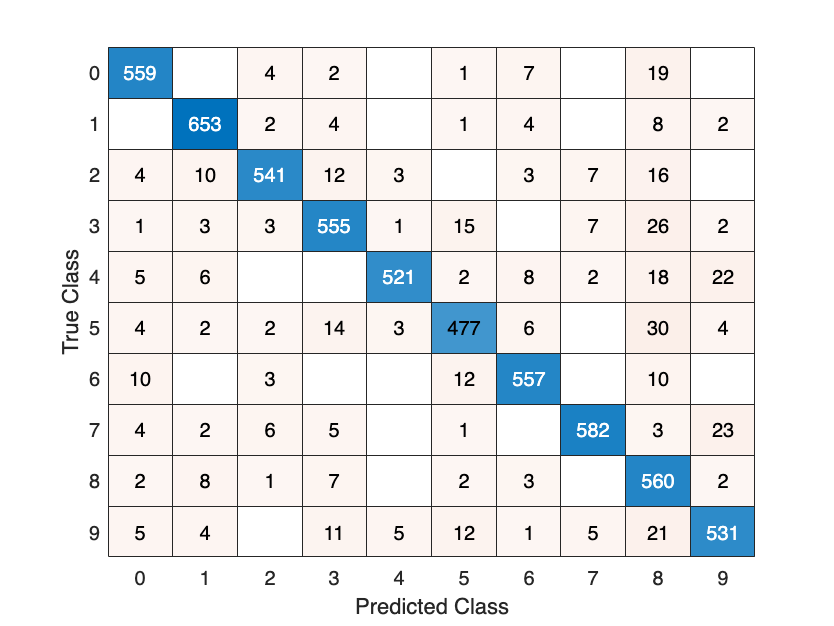


confusionchart(imdsPrediction.Labels, categorical(labelSa));

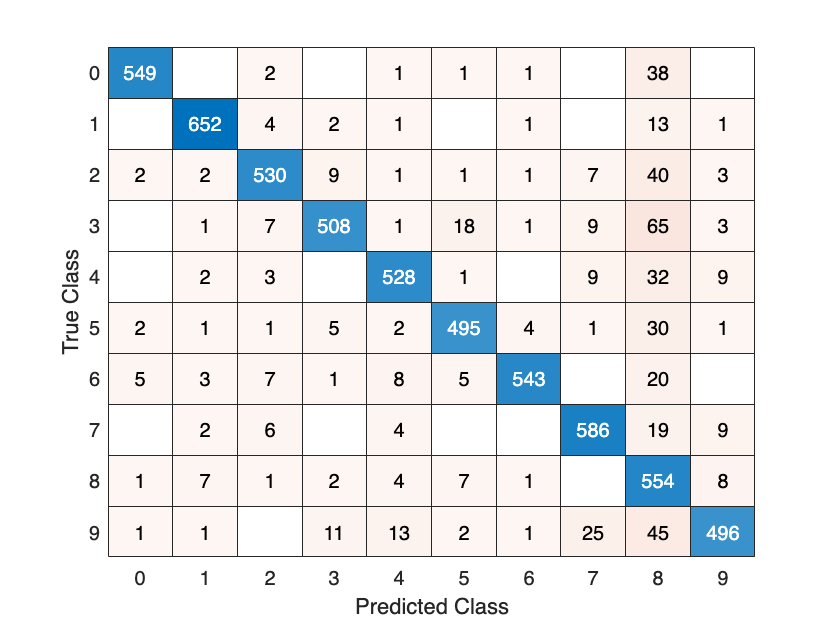


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelSa));

confusionchart(imdsPrediction.Labels, categorical(labelSb));

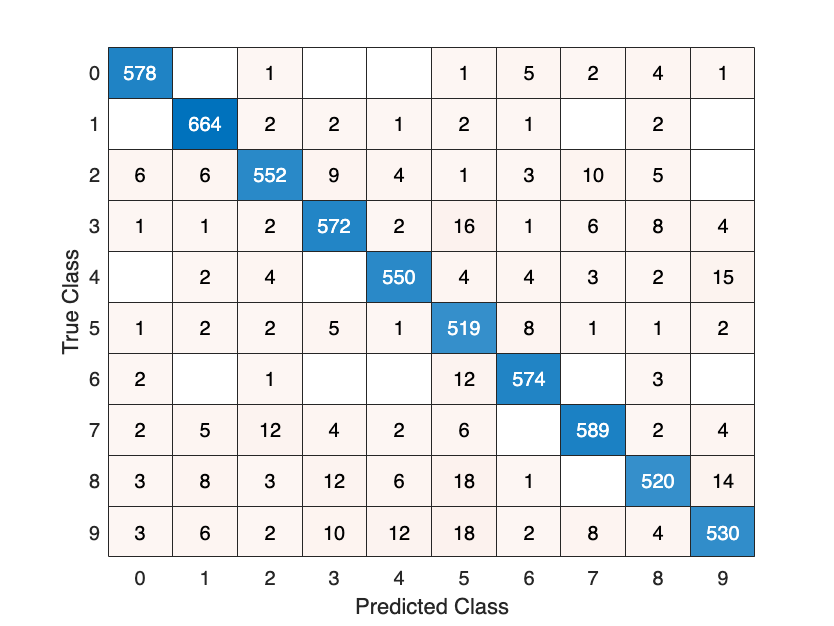


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelSb));

confusionchart(imdsPrediction.Labels, categorical(labelSc));


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelSc));

Ici de même et c'est une conclusion que l'on va pouvoir appliquer à chaque étude d'influences, le 5 et le 8 sont les valeurs les moins bien prédites car présentant le plus d'ambiguité contrairement au 1.

### Influence du Learning Rate

Nous avons choisi 3 Learning Rate (10, 0,05 0,00001,rmsprop) avec des écarts signficativement grands afin de pouvoir observer une différence et en tirer des conclusions.

layersLR = [imageInputLayer([28 28 1])
    fullyConnectedLayer(128)
    reluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];

optionsLR1 = trainingOptions("sgdm", ...
    InitialLearnRate=10, ... 
    MaxEpochs=5, ...
    MiniBatchSize=64, ...
    ValidationFrequency=30, ...
    ValidationData=imdsValidation)

optionsLR1 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 10
                       MaxEpochs: 5
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 64
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 30
              ValidationPatience: Inf
       


optionsLR2 = trainingOptions("sgdm", ...
    InitialLearnRate=0.05,...   
    MaxEpochs=5, ...
    MiniBatchSize=64, ...
    ValidationFrequency=30, ...
    ValidationData=imdsValidation)

optionsLR2 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 0.0500
                       MaxEpochs: 5
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 64
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 30
              ValidationPatience: Inf
   


optionsLR3 = trainingOptions("sgdm", ...
    InitialLearnRate=0.00001,...   
    MaxEpochs=5, ...
    MiniBatchSize=64, ...
    ValidationFrequency=30, ...
    ValidationData=imdsValidation)

optionsLR3 =   TrainingOptionsSGDM with properties:

                        Momentum: 0.9000
                InitialLearnRate: 1.0000e-05
                       MaxEpochs: 5
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 64
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.ImageDatastore]
             ValidationFrequency: 30
              ValidationPatience: Inf


[netLRa, traininfoLRa] = trainNetwork(imdsTrain,layersLR,optionsLR1)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |        6.25% |        9.74% |     188.5137 |   1.7331e+09 |         10.0000 |
|       1 |          27 |       00:00:01 |        6.25% |              |          NaN |              |         10.0000 |
|======================================================================================================================|
Training finished: Training loss is NaN.


netLRa =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoLRa = struct with fields:
               TrainingLoss: [188.5137 1.7679e+09 5.5755e+12 1.1062e+18 2.6914e+22 6.2198e+20 299421696 2.8712e+05 4.6630e+16 4.8079e+19 1.7690e+14 2.2693e+21 1.8206e+26 17.2088 18.2997 3.0175e+11 2.5126e+15 13.7093 12.6558 1.9951e+24 … ] (1×27 double)
           TrainingAccuracy: [6.2500 10.9375 10.9375 18.7500 14.0625 17.1875 10.9375 4.6875 7.8125 7.8125 3.1250 7.8125 6.2500 10.9375 9.3750 3.1250 7.8125 7.8125 14.0625 10.9375 9.3750 4.6875 10.9375 10.9375 9.3750 1.5625 6.2500]
             ValidationLoss: [1.7331e+09 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN]
         ValidationAccuracy: [9.7417 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 9.8750]
              BaseLearnRate: [10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10 10]
        FinalValidationLoss: NaN
    FinalValidationAccuracy: 9.8750
     Outp

[netLRb, traininfoLRb] = trainNetwork(imdsTrain,layersLR,optionsLR2)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |       15.62% |        9.74% |     130.5036 |   10248.7939 |          0.0500 |
|       1 |          30 |       00:00:02 |        9.38% |       10.42% |    1186.3213 |   19069.7070 |          0.0500 |
|       1 |          50 |       00:00:02 |        7.81% |              |       2.3049 |              |          0.0500 |
|       1 |          60 |       00:00:03 |       10.94% |       10.43% |   24723.7012 |   

netLRb =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoLRb = struct with fields:
               TrainingLoss: [130.5036 1.0618e+04 1.1687e+05 2119978 3.8489e+06 10906518 4.5380e+06 2195802 3.0673e+06 5.0379e+04 8.9235e+03 2.2054 2.3081 22.7103 4.9812e+05 2.3302 2.3275 2.3297 2.3310 2.2860 80.3370 7.8159 2.3815 … ] (1×3280 double)
           TrainingAccuracy: [15.6250 7.8125 7.8125 10.9375 17.1875 18.7500 18.7500 7.8125 20.3125 31.2500 15.6250 12.5000 9.3750 18.7500 20.3125 7.8125 7.8125 10.9375 12.5000 14.0625 10.9375 7.8125 6.2500 15.6250 14.0625 14.0625 … ] (1×3280 double)
             ValidationLoss: [1.0249e+04 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 1.9070e+04 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [9.7417 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 10.4167 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN

[netLRc, traininfoLRc] = trainNetwork(imdsTrain,layersLR,optionsLR3)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |        9.38% |        7.22% |     114.5976 |     135.0092 |      1.0000e-05 |
|       1 |          30 |       00:00:02 |       60.94% |       49.37% |      21.9118 |      29.1972 |      1.0000e-05 |
|       1 |          50 |       00:00:02 |       59.38% |              |      19.8831 |              |      1.0000e-05 |
|       1 |          60 |       00:00:03 |       70.31% |       67.18% |      15.6459 |   

netLRc =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoLRc = struct with fields:
               TrainingLoss: [114.5976 138.0614 136.7575 134.9428 117.3005 104.9308 112.3574 101.1962 114.5748 96.7283 69.8007 81.4205 80.3331 57.9702 68.7838 66.7960 57.6940 61.5724 52.6909 53.7680 47.4869 53.6193 45.7459 36.0316 … ] (1×3280 double)
           TrainingAccuracy: [9.3750 6.2500 4.6875 6.2500 10.9375 6.2500 6.2500 14.0625 4.6875 7.8125 14.0625 12.5000 20.3125 26.5625 20.3125 18.7500 29.6875 21.8750 29.6875 32.8125 28.1250 32.8125 23.4375 40.6250 32.8125 39.0625 … ] (1×3280 double)
             ValidationLoss: [135.0092 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 29.1972 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×3280 double)
         ValidationAccuracy: [7.2167 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 49.3667 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 



[labelLRa, scoreLRa] = classify(netLRa,imdsPrediction);
[labelLRb, scoreLRb] = classify(netLRb,imdsPrediction);
[labelLRc, scoreLRc] = classify(netLRc,imdsPrediction);

L'impact du taux d'apprentissage (Learning Rate) sur les performances du réseau de neurones se manifeste clairement dans les résultats obtenus. Avec un Learning Rate élevé de 10, le modèle a une faible précision de 9,8750% et une perte indéterminée (NaN), indiquant une convergence très inefficace. En réduisant le Learning Rate à 0,05, la précision augmente légèrement à 10,4667%, mais la perte reste extrêmement élevée à 258,5359, suggérant toujours une performance médiocre. Un Learning Rate très faible de 0,00001 présente la meilleure performance avec une précision de 89,9667% et une perte gérable de 2,2253, montrant une amélioration significative dans l'apprentissage du modèle.

En classant les taux d'apprentissage du moins efficace au plus efficace : un Learning Rate de 10 présente les performances les plus faibles. Le Learning Rate de 0,05 offre une légère amélioration Le meilleur résultat est obtenu avec un Learning Rate de 0,00001.

#### Vérification par des métriques

#### Matrice de confusion

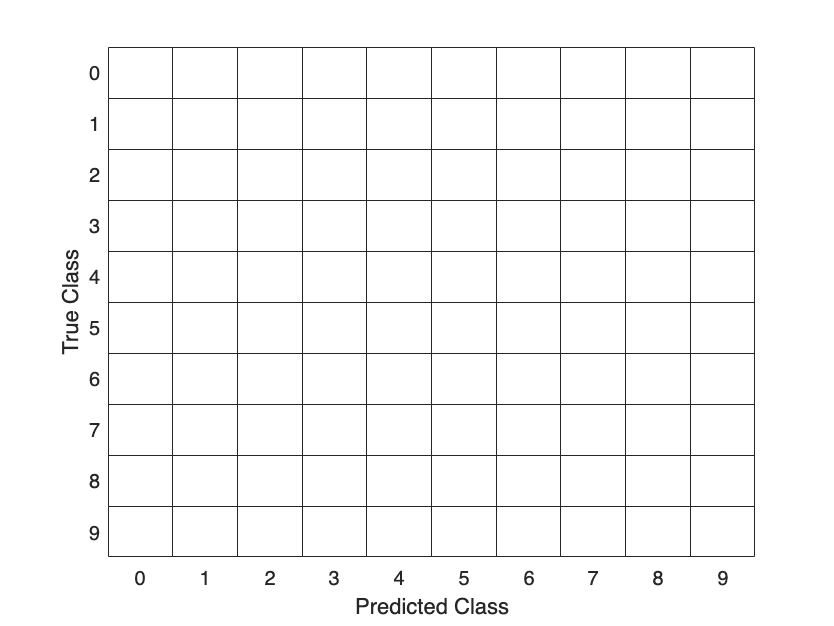

confusionchart(imdsPrediction.Labels, categorical(labelLRa));

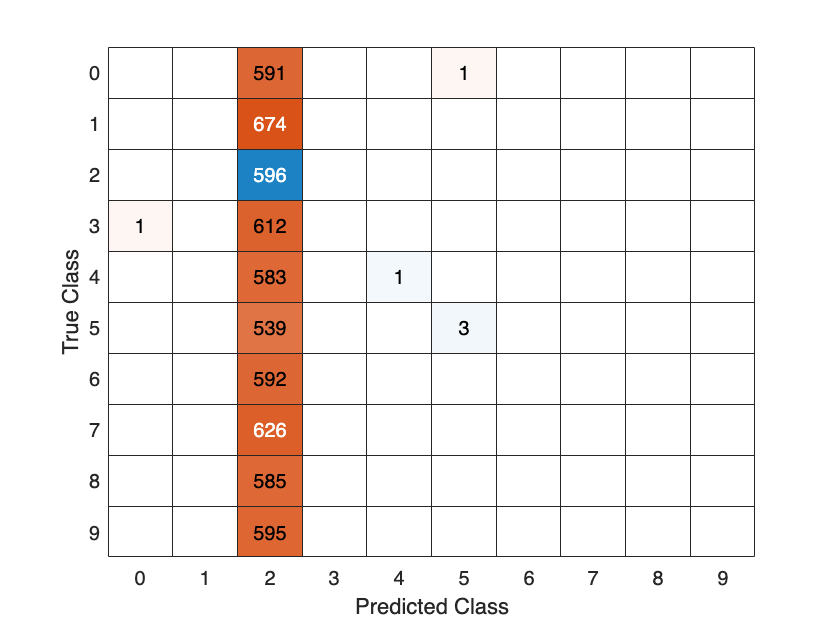


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelLRa));

confusionchart(imdsPrediction.Labels, categorical(labelLRb));

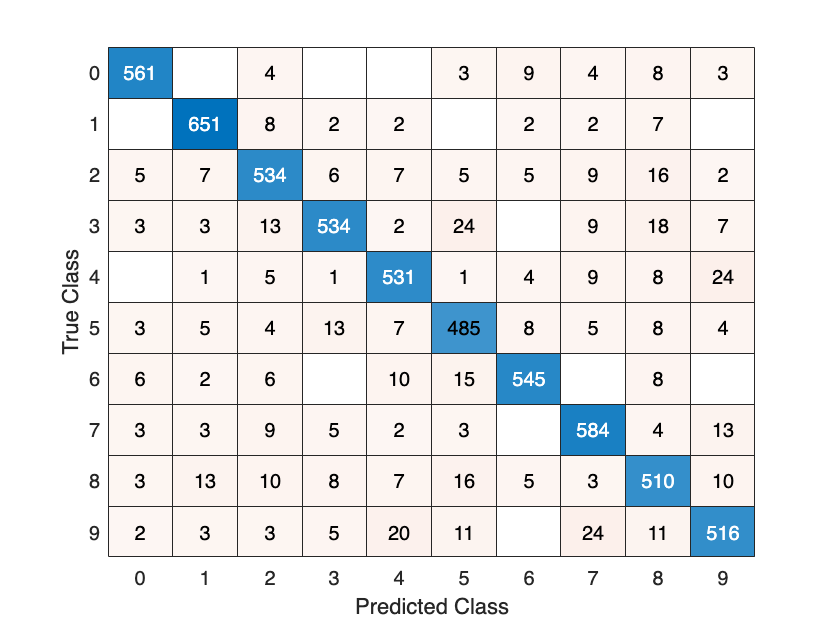


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelLRb));

confusionchart(imdsPrediction.Labels, categorical(labelLRc));


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelLRc));

Nous ne pouvons pas visualiser les matrices de confusion car la couche ne s'est pas bien chargé mais nous on en déduirions la même chose. 

## Conclusion sur l'influence

Les performances d'un réseau de neurones sont influencées par le choix du nombre de neurones, des fonctions d'activation, des solveurs et du taux d'apprentissage. Une augmentation du nombre de neurones améliore généralement la précision et réduit la perte. Concernant les fonctions d'activation, eluLayer a montré les meilleures performances, suivie de tanhLayer, swishLayer, et reluLayer. Parmi les solveurs, rmsprop a obtenu la plus haute précision, surpassant Adam et sgdm. Enfin, un taux d'apprentissage plus faible a conduit à de meilleures performances, avec 0,00001 étant le plus efficace parmi les valeurs testées.

## Comparaison entre le MNIST et ZALANDO

## Choix du réseau le plus optimisé

Nous allons à presént utiliser le jeu de données ZALANDO qui recense des images de vêtements par classe. Il est de la même taille que le NMIST et joue également sur des la reconnaissance d'images ce qui justifie le choix de ce jeu de donénes pour comparer. 

Chaque dataset est associé à ces outputs: 

0 T-shirt/top 

1 Trouser 

2 Pullover 

3 Dress 

4 Coat 

5 Sandal 

6 Shirt 

7 Sneaker 

8 Bag 

9 Ankle boot

Ainsi, nous choisirons le réseau le plus optimisé suivant:

imdsTrain = imageDatastore("DatasetMNIST/MNIST Dataset JPG format/MNIST - JPG - testing","IncludeSubfolders",true,"LabelSource","foldernames");
[imdsTrain, imdsValidation ,imdsPrediction] = splitEachLabel(imdsTrain,0.7,0.2,0.1,'randomized');
% Resize the images to match the network input layer.
augimdsTrain = augmentedImageDatastore([28 28 1],imdsTrain);
augimdsValidation = augmentedImageDatastore([28 28 1],imdsValidation);
augimdsPrediction = augmentedImageDatastore([28 28 1],imdsPrediction);

imdsTrain2 = imageDatastore("zalando/test","LabelSource","foldernames","FileExtensions",".png","IncludeSubfolders",true);
[imdsTrain2, imdsValidation2 ,imdsPrediction2] = splitEachLabel(imdsTrain2,0.7,0.2,0.1,'randomized');
% Resize the images to match the network input layer.
augimdsTrain2 = augmentedImageDatastore([28 28 1],imdsTrain2);
augimdsValidation2 = augmentedImageDatastore([28 28 1],imdsValidation2);
augimdsPrediction2 = augmentedImageDatastore([28 28 1],imdsPrediction2);


layersOpt = [
    imageInputLayer([28 28 1])
    fullyConnectedLayer(1000)
    eluLayer
    fullyConnectedLayer(10)
    softmaxLayer
    classificationLayer
    ];


optionsOpt = trainingOptions("adam", ...
    InitialLearnRate=0.00001,...   
    MaxEpochs=5, ...
    MiniBatchSize=64, ...
    ValidationFrequency=30, ...
    ValidationData=imdsValidation)

optionsOpt =   TrainingOptionsADAM with properties:

             GradientDecayFactor: 0.9000
      SquaredGradientDecayFactor: 0.9990
                         Epsilon: 1.0000e-08
                InitialLearnRate: 1.0000e-05
                       MaxEpochs: 5
               LearnRateSchedule: 'none'
             LearnRateDropFactor: 0.1000
             LearnRateDropPeriod: 10
                   MiniBatchSize: 64
                         Shuffle: 'once'
                      WorkerLoad: []
             CheckpointFrequency: 1
         CheckpointFrequencyUnit: 'epoch'
                  SequenceLength: 'longest'
            DispatchInBackground: 0
                L2Regularization: 1.0000e-04
         GradientThresholdMethod: 'l2norm'
               GradientThreshold: Inf
                         Verbose: 1
                VerboseFrequency: 50
                  ValidationData: [1×1 matlab.io.datastore.Imag


[netOpt, traininfoOpt] = trainNetwork(imdsTrain,layersOpt,optionsOpt)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |        6.25% |        9.45% |     110.6541 |     113.5145 |      1.0000e-05 |
|       1 |          30 |       00:00:01 |       10.94% |       17.89% |      65.8670 |      70.5138 |      1.0000e-05 |
|       1 |          50 |       00:00:01 |       39.06% |              |      47.0152 |              |      1.0000e-05 |
|       1 |          60 |       00:00:01 |       28.12% |       29.39% |      46.5440 |   

netOpt =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoOpt = struct with fields:
               TrainingLoss: [110.6541 101.5430 107.3236 104.7436 101.7099 104.6971 100.1460 105.4831 108.4669 102.7697 101.4595 89.2072 85.6375 99.8280 105.9336 95.9837 95.3519 84.6312 98.9952 94.0342 93.2392 65.6750 67.8569 80.1829 … ] (1×545 double)
           TrainingAccuracy: [6.2500 6.2500 10.9375 14.0625 10.9375 7.8125 15.6250 4.6875 9.3750 9.3750 6.2500 9.3750 15.6250 9.3750 9.3750 14.0625 7.8125 12.5000 17.1875 17.1875 12.5000 23.4375 23.4375 15.6250 18.7500 15.6250 12.5000 … ] (1×545 double)
             ValidationLoss: [113.5145 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 70.5138 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×545 double)
         ValidationAccuracy: [9.4453 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 17.8911 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN

[netOpt2, traininfoOpt2] = trainNetwork(imdsTrain2,layersOpt,optionsOpt)

Training on single CPU.
Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:00 |        4.69% |        8.55% |     145.3897 |     138.5590 |      1.0000e-05 |
|       1 |          30 |       00:00:01 |       28.12% |        7.90% |      47.7684 |     109.0793 |      1.0000e-05 |
|       1 |          50 |       00:00:01 |       39.06% |              |      33.8461 |              |      1.0000e-05 |
|       1 |          60 |       00:00:02 |       53.12% |        7.80% |      23.3487 |   

netOpt2 =   SeriesNetwork with properties:

         Layers: [6×1 nnet.cnn.layer.Layer]
     InputNames: {'imageinput'}
    OutputNames: {'classoutput'}


traininfoOpt2 = struct with fields:
               TrainingLoss: [145.3897 138.5441 134.9046 102.8131 110.7079 98.6418 99.0678 83.0220 85.7800 82.9687 96.9121 75.0333 77.7510 74.4853 73.9179 61.4804 65.7872 67.7351 65.1135 62.6169 49.8630 47.0086 53.6963 57.9410 51.0991 … ] (1×545 double)
           TrainingAccuracy: [4.6875 4.6875 6.2500 18.7500 7.8125 12.5000 12.5000 18.7500 6.2500 17.1875 10.9375 15.6250 17.1875 12.5000 18.7500 21.8750 10.9375 20.3125 18.7500 15.6250 17.1875 29.6875 31.2500 21.8750 26.5625 18.7500 … ] (1×545 double)
             ValidationLoss: [138.5590 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 109.0793 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN … ] (1×545 double)
         ValidationAccuracy: [8.5457 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN 7.8961 NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN NaN



analyzeNetwork(layersOpt)


[labelOpt, scoreOpt] = classify(netOpt,imdsPrediction);
[labelOpt2, scoreOpt2] = classify(netOpt2,imdsPrediction);


Nous obtenons les résultats suivants:

- MNIST: accuracy= 78,0610 et loss=7,6293

- Zalando: accuracy= 8,2459 et loss=85,5468

Comme prévu, le jeu de données zalando nous donne une mauvaise précision et une perte très élevée car celui-ci est beaucoup plus complexe que le MNIST avec de simples nombres. 

Le MNIST quant à lui présente des résultats moins fulgurants que ceux lors des tests d'influence, ce qui est normal étant donén qu'il s'agit du jeu de données testing et que on a modifié tous les paramètres avec les paramètres optimaux. De plus, il est à noté que nous avons beaucoup moins de valeurs ce qui impacte grandement. Cependant, le résultat reste acceptable.

### Evaluation de performance

Nous nous interessons maintenat aux performances de ce réseau:

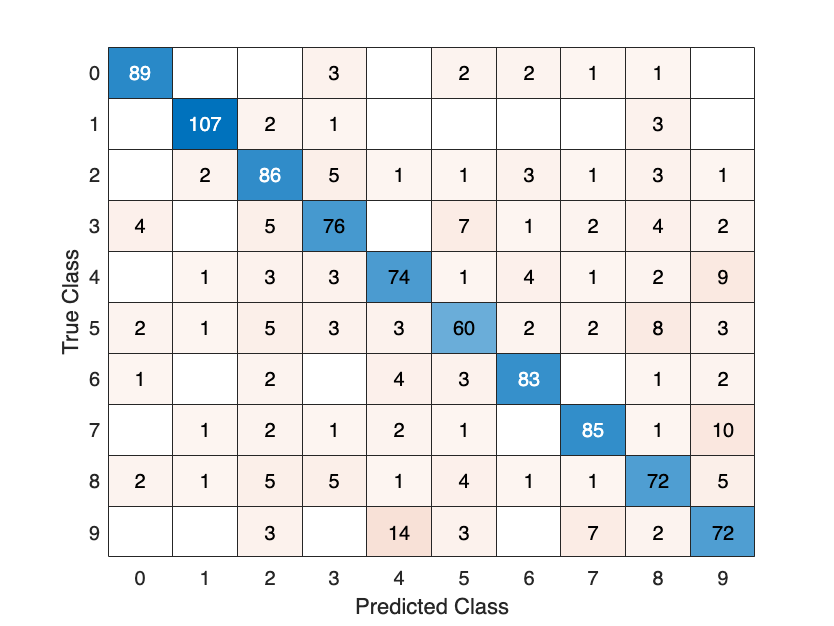

confusionchart(imdsPrediction.Labels, categorical(labelOpt));

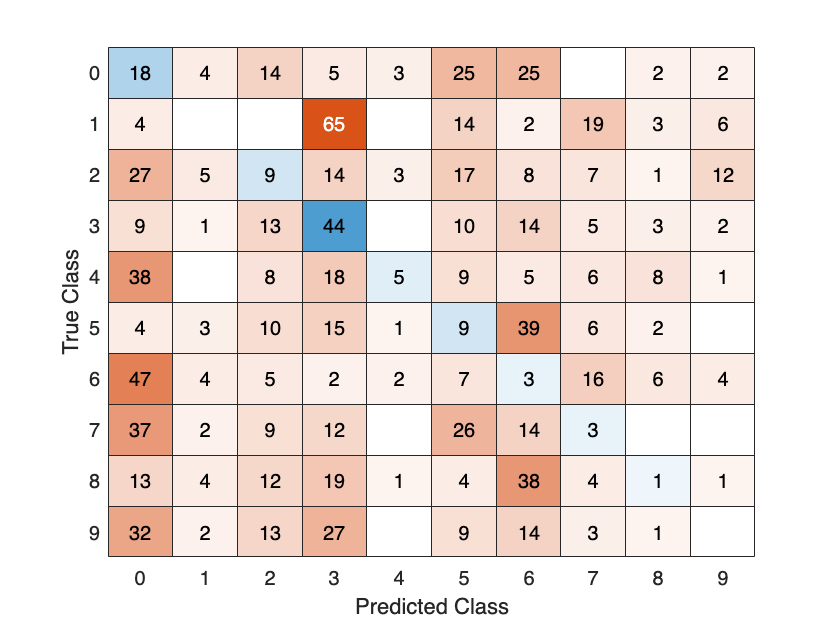


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelOpt));

confusionchart(imdsPrediction.Labels, categorical(labelOpt2));


% Calcul de la matrice de confusion
c_matrix = confusionmat(double(imdsPrediction.Labels), double(labelOpt2));

Dans notre cas, comme precedemment pour le MNIST lors du train, les valeurs sont globalement bien prédites notamment pour le 1 mis à part pour le 8 et le 5 qui sont ambigue pour le réseau.

Pour zalando, il en est tout autrement car quasiment aucune valeur n'est bien prédites. Ce résultat parait cohérent car il est plus difficile d'analyser une image contenant un vêtement avec autant de détails mais il st surprenant qu'il puisse avoir autant d'ambiguité étant donné que les vêtements ont des allures très différentes.

## **Conclusion**

En conclusion, cette étude démontre que les performances d'un réseau de neurones sont significativement influencées par plusieurs paramètres clés. L'augmentation du nombre de neurones tend à améliorer la précision et à diminuer la perte. Parmi les fonctions d'activation, eluLayer se distingue comme la plus efficace, suivie de près par tanhLayer, swishLayer, et reluLayer. Le choix du solveur est également crucial, rmsprop ayant surpassé Adam et sgdm. Un taux d'apprentissage plus bas a prouvé être optimal, spécifiquement 0,00001. Il faut tout de même resté critique face aux résultats car il se peut qu'un phénomène d'overfitting se soit produit et donc compromette les résultats. Lors de l'application sur les jeux de données MNIST et Zalando, nous observons que MNIST affiche des résultats satisfaisants malgré des performances moindres comparées aux tests d'influence, tandis que Zalando présente des difficultés notables en raison de sa complexité accrue, soulignant les défis rencontrés lors de la classification d'images plus détaillées et variées. 